analyse the simulated data

first check the nascent data is sane

What does the ground truth look like

fDir = 'D:\data\z dynamics paper\nascent_zdynamic_sim\nascentDensity'

fDir = 'D:\data\z dynamics paper\nascent_zdynamic_sim\nascentDensity'

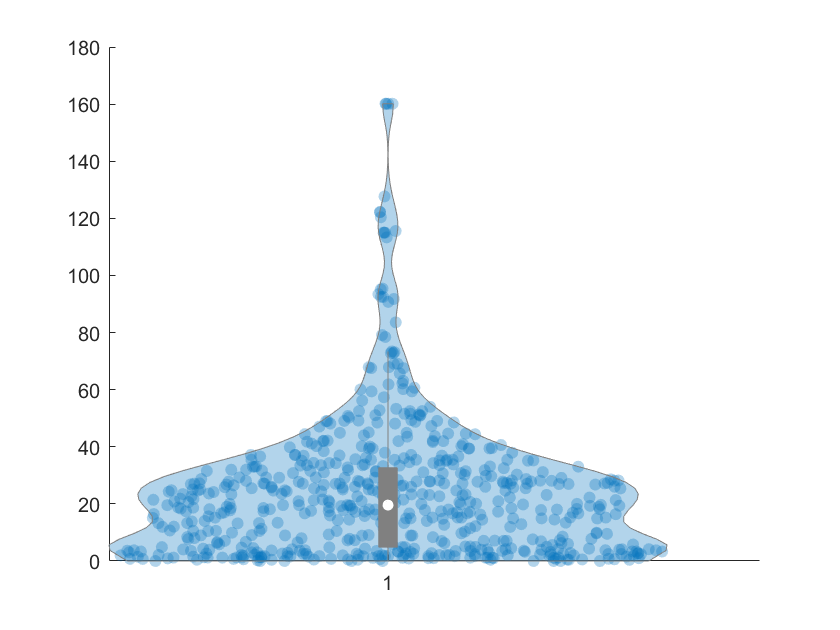

fname='simZRing_nAvg6_';
GT_stub='_GT.mat';
nFile=100;
trackTableGT =table;
%ii=1;
for ii =1:nFile
    ii;
    fCur= fullfile(fDir,[fname,sprintf('%03i', ii),GT_stub]);
    load(fCur,'groundTruth','simPar','nTrackAvg');
    trackTableGT=[trackTableGT;groundTruth.trackTable];
end
figure
violinplot(trackTableGT.S);

size(trackTableGT,1)

ans = 600

analysed tracks

analysedFname=fullfile(fDir,'analysed/analysed_tracks_global.csv');
trackObs=readtable(analysedFname);

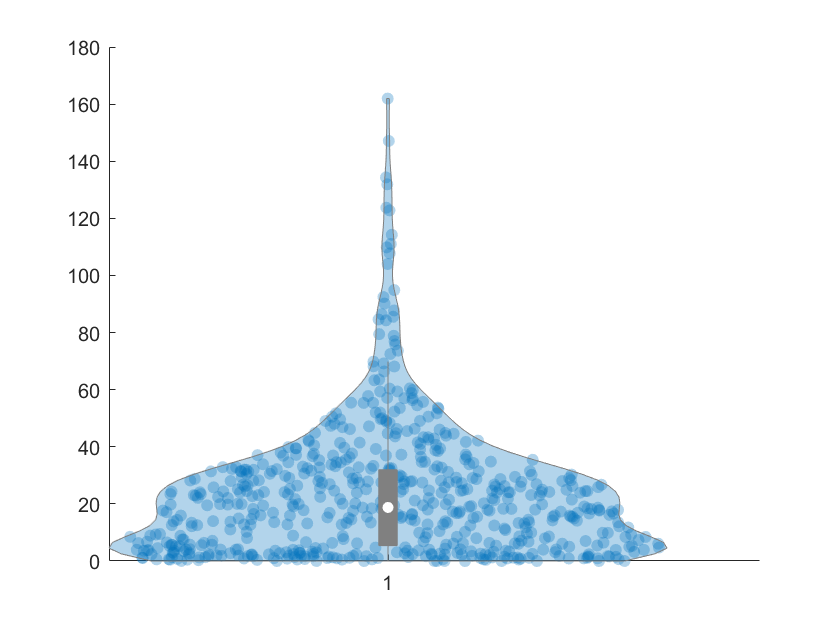

s=abs(trackObs.Speed_nm_s_);
figure;
violinplot(s);

Matches the GT pretty well

better check all tracks are really included in sim (sanity check)


ii=1;

fname=['simZRing_nAvg6_', sprintf('%03i', ii)]

fname = 'simZRing_nAvg6_001'

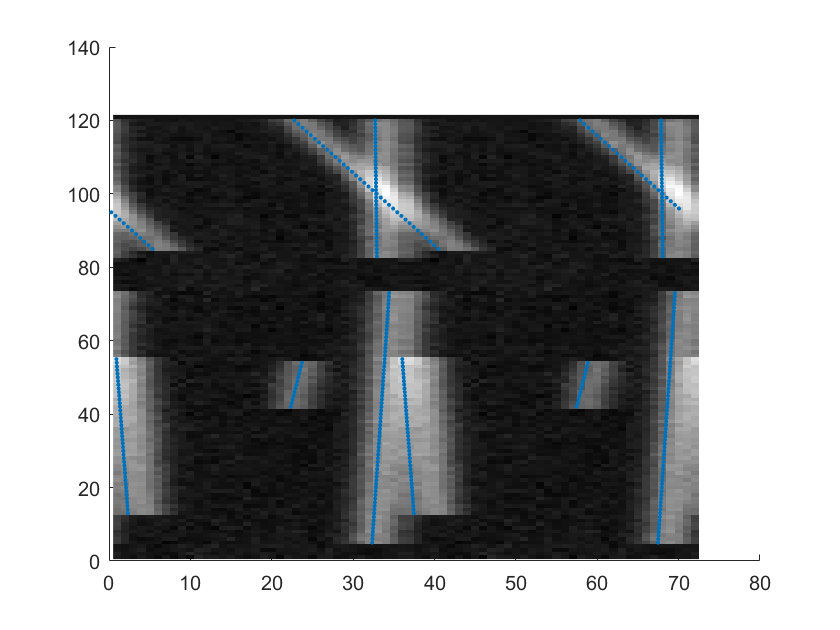

GT=load(fullfile(fDir,[fname,GT_stub]),'groundTruth');
GT=GT.groundTruth;
kymoIm = imread(fullfile(fDir,'analysed',[fname,'_denoise_kymoWrap.tif']));
f= load(fullfile(fDir,'analysed',[fname,'_denoise_fitData.mat']),'kymoInfo');
kymoInfo=f.kymoInfo;
diam=kymoInfo(1,2)*2;
theta=GT.trackCoord.theta;
fr=GT.trackCoord.fr;
%double up the angles
theta=[theta;theta+2*pi];
fr=repmat(fr,2,1);  
arcPix = theta*diam/(2*simPar.pixSizenm);
figure;
hold all;
imagesc(kymoIm);
colormap gray;
plot(arcPix,fr,'.')


s=[];
t=[]


t =

     []



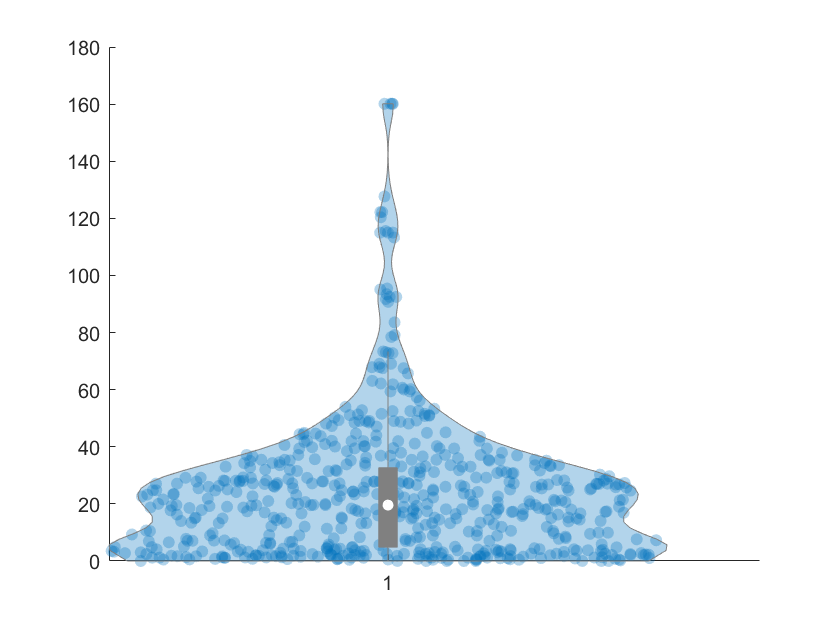

ans =   Violin with properties:

    ScatterPlot: [1×1 Scatter]
     ViolinPlot: [1×1 Patch]
        BoxPlot: [1×1 Patch]
    WhiskerPlot: [1×1 Line]
     MedianPlot: [1×1 Scatter]
     NotchPlots: [1×2 Scatter]
       MeanPlot: [1×1 Line]
    ViolinColor: [0 0.4470 0.7410]
    ViolinAlpha: 0.3000
      EdgeColor: [0.5000 0.5000 0.5000]
       BoxColor: [0.5000 0.5000 0.5000]
       BoxWidth: 0.0200
    MedianColor: [1 1 1]
       ShowData: 1
    ShowNotches: 0
       ShowMean: 0


fileNo=[];
ii=1;
for ii =1:100
    sFile=[];
    tFile=[];
    fname=['simZRing_nAvg6_', sprintf('%03i', ii)];
    GT=load(fullfile(fDir,[fname,GT_stub]),'groundTruth');
    GT=GT.groundTruth;
    trackNo=unique(GT.trackCoord.id);
    for jj=trackNo'
        thetaCur= GT.trackCoord.theta(GT.trackCoord.id==jj);
        if numel(thetaCur)>=2
            sCur=abs(min(mod(thetaCur(2)-thetaCur(1),2*pi),mod(thetaCur(1)-thetaCur(2),2*pi)))*880/2;
            sFile=[sFile;sCur];
            tFile=[tFile;thetaCur(1)];
        end
    end
    fileNo=[fileNo;ii*ones(size(sFile))];
    s=[s;sFile];
    t=[t;tFile];
end
gtResult=table(fileNo,s,t);

figure;
violinplot(gtResult.s)

tested GT is valid as much as possible

analyse all the conditions

fDir2 = 'D:\data\z dynamics paper\nascent_zdynamic_sim\'

fDir2 = 'D:\data\z dynamics paper\nascent_zdynamic_sim\'

analysedFname=fullfile(fDir2,'nascentDensity/analysed/analysed_tracks_global.csv');
trackObs_nas=readtable(analysedFname);

s_nas=abs(trackObs_nas.Speed_nm_s_);

analysedFname=fullfile(fDir2,'matureDensity/analysed/analysed_tracks_global.csv');
trackObs_mat=readtable(analysedFname);

s_mat=abs(trackObs_mat.Speed_nm_s_);

analysedFname=fullfile(fDir2,'2xmatureDensity/analysed/analysed_tracks_global.csv');
trackObs_2xmat=readtable(analysedFname);

s_2xmat=abs(trackObs_2xmat.Speed_nm_s_);

analysedFname=fullfile(fDir2,'ericksonDensity/analysed/analysed_tracks_global.csv');
trackObs_erick=readtable(analysedFname);

s_erick=abs(trackObs_erick.Speed_nm_s_);

load('nascentTrackData.mat','S');
S_gt=S;

obs=table;
obs.speed=[s_nas;s_mat;s_2xmat;s_erick;S];
numel(s_nas)

ans = 603

numel(s_mat)

ans = 1446

numel(s_2xmat)

ans = 2712

numel(s_erick)

ans = 2252

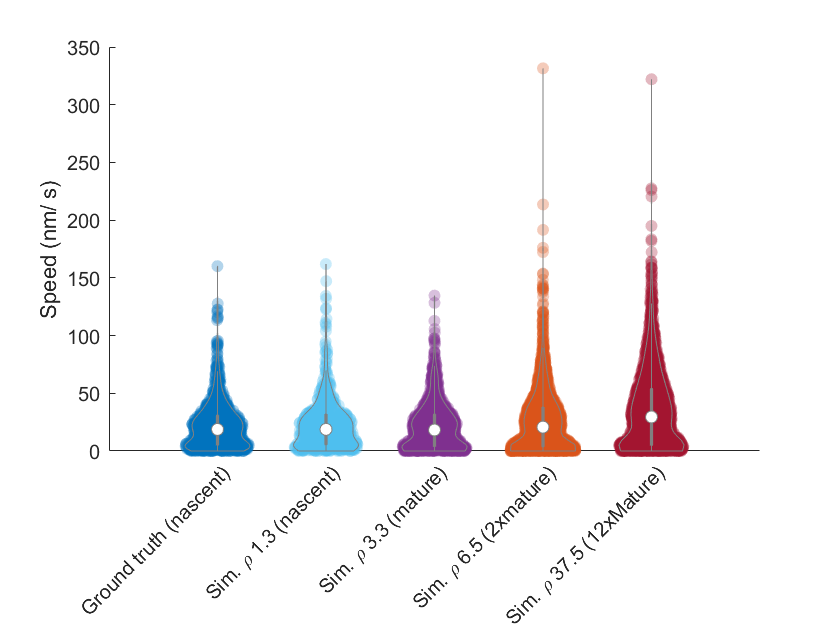

obs.name=[repmat({'Sim. \rho 1.3 (nascent)'},size(s_nas));...
          repmat({'Sim. \rho 3.3 (mature)'},size(s_mat));...
          repmat({'Sim. \rho 6.5 (2xmature)'},size(s_2xmat));...
          repmat({'Sim. \rho 37.5 (12xMature)'},size(s_erick));...`
          repmat({'Ground truth (nascent)'},size(S_gt))];
grouporder= {'Ground truth (nascent)',...
            'Sim. \rho 1.3 (nascent)',...
            'Sim. \rho 3.3 (mature)',...
            'Sim. \rho 6.5 (2xmature)',...
            'Sim. \rho 37.5 (12xMature)'};
        
f1=figure;
violinplot(obs.speed,obs.name,'GroupOrder',grouporder);
ylabel('Speed (nm/ s)');
h=gca;
h.XTickLabelRotation=45;
f1.Visible='on';
saveas(f1,'zSim_speeds.fig');

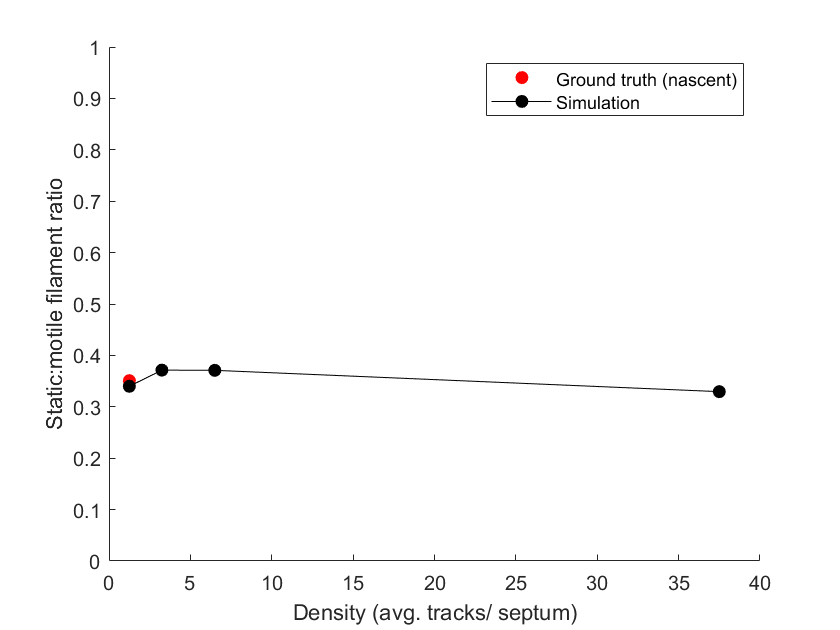


staticFraction=@(s) (numel(find(s<=10))/numel(s));
fStatic=[staticFraction(S_gt);...
         staticFraction(s_nas);...
         staticFraction(s_mat);...
         staticFraction(s_2xmat);...
         staticFraction(s_erick);];
        
rho=[6;6;15.6;31.2;180]*25/120;
f1=figure;
hold all
plot(rho(1),fStatic(1),'ro','MarkerFaceColor','r');
plot(rho(2:end),fStatic(2:end),'ko-','MarkerFaceColor','k');
legend('Ground truth (nascent)','Simulation');
xlabel('Density (avg. tracks/ septum)');
ylabel('Static:motile filament ratio');
ylim([0 1]);
f1.Visible='on';
saveas(f1,'zSim_staticmotileRatio.fig');

what are the number of obs filaments vs GT.

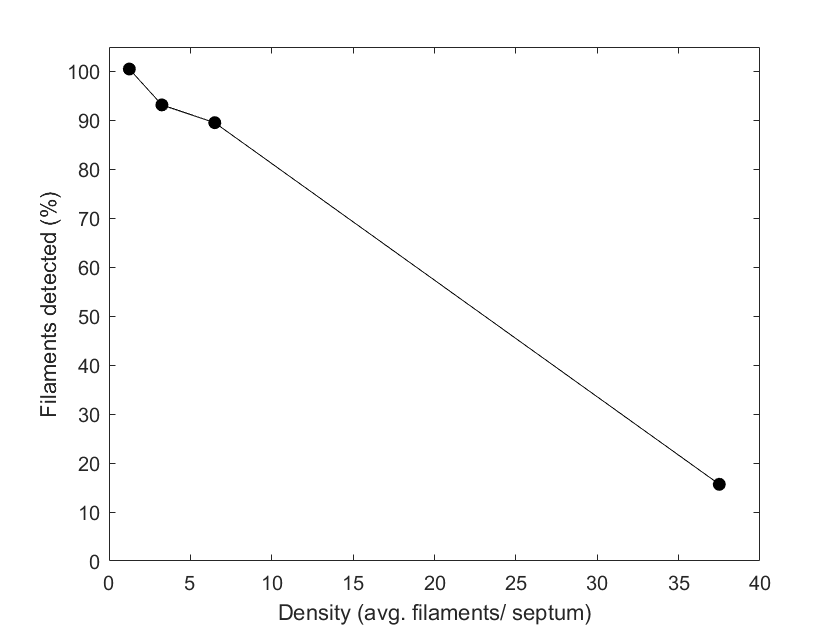

fDir = {'D:\data\z dynamics paper\nascent_zdynamic_sim\nascentDensity';...
        'D:\data\z dynamics paper\nascent_zdynamic_sim\matureDensity';...
        'D:\data\z dynamics paper\nascent_zdynamic_sim\2xmatureDensity';...
        'D:\data\z dynamics paper\nascent_zdynamic_sim\ericksonDensity'};
fnameStub={'simZRing_nAvg6_',...
           'simZRing_nAvg15.6_',...
           'testSimRing_nAvg31.2_',...
           'testSimRing_nAvg180_'};
nSimFile=[100,100,100,80];
rhoSim=[6;15.6;31.2;180]*25/120;
nObs=[   numel(s_nas);...
         numel(s_mat);...
         numel(s_2xmat);...
         numel(s_erick);];
     
for kk=1:4
    fileNo=[];
    ii=1;
    s=[];
    for ii =1:nSimFile(kk)
        sFile=[];
        tFile=[];
        fname=[fnameStub{kk}, sprintf('%03i', ii)];
        GT=load(fullfile(fDir{kk},[fname,GT_stub]),'groundTruth');
        GT=GT.groundTruth;
        trackNo=unique(GT.trackCoord.id);
        for jj=trackNo'
            thetaCur= GT.trackCoord.theta(GT.trackCoord.id==jj);
            if numel(thetaCur)>=2
                sCur=abs(min(mod(thetaCur(2)-thetaCur(1),2*pi),mod(thetaCur(1)-thetaCur(2),2*pi)))*880/2;
                sFile=[sFile;sCur];
                tFile=[tFile;thetaCur(1)];
            end
        end
        fileNo=[fileNo;ii*ones(size(sFile))];
        s=[s;sFile];
        t=[t;tFile];
    end
    n_gt(kk)=numel(s);
    fracDetected(kk)= nObs(kk)/n_gt(kk);
end

f1=figure;
plot(rhoSim,fracDetected*100,'ko-','MarkerFaceColor','k');
ylim([0 105]);
xlabel('Density (avg. filaments/ septum)');
ylabel('Filaments detected (%)');

how to calculate error bars on detected fraction

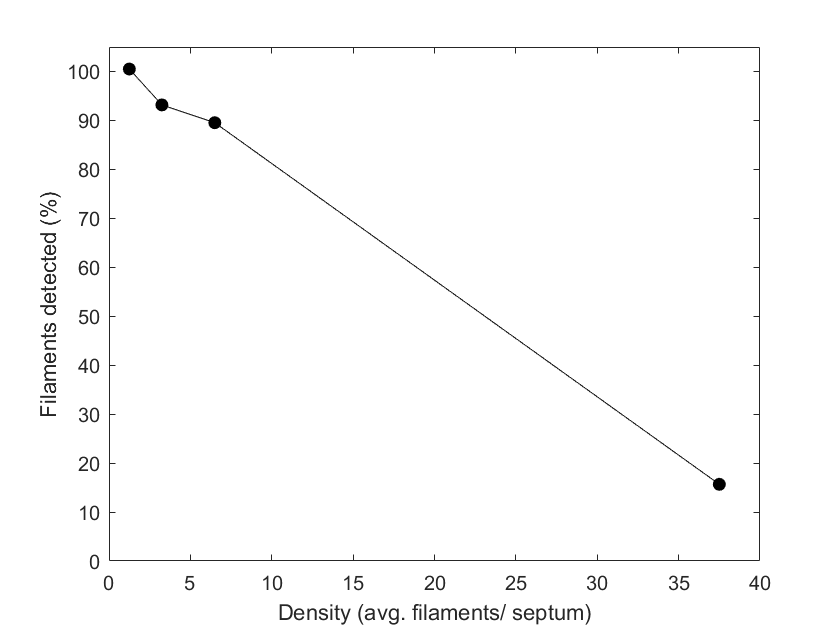

f1.Visible='on';

saveas(f1,'zSim_filamentsDetected.fig');

fracMotileList=[];
fracMotileMu=[];
regStr={'_0[0-1][0-9]_','_0[2-3][0-9]_','_0[4-5][0-9]_','_0[6-7][0-9]_','_0[8-9][0-9]_'};
%nascent
for jj=1:4
    
    switch jj
        case 1
            trackObs=trackObs_nas;
        case 2
            trackObs=trackObs_mat;
        case 3
            trackObs=trackObs_2xmat;
        case 4
            trackObs=trackObs_erick;
    end

    for ii=1:5
        regList=regexp(trackObs.Image_ROI_Name,regStr{ii});
        trackRow=~cellfun(@isempty,regList);
        s=abs(trackObs.Speed_nm_s_(trackRow));
        if ii==5 && jj==4
            fracMotileList(ii,jj)=NaN;
        else
            fracMotileList(ii,jj)=staticFraction(s);
        end
    end

end


ok plot the above as updated scatter plot

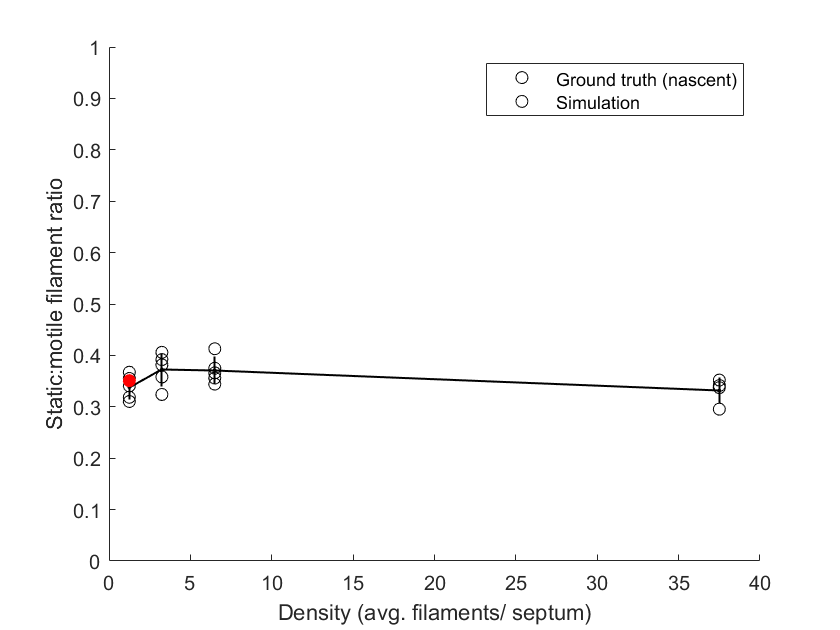

fracMotileMu=nanmean(fracMotileList);
fracMotileStd = nanstd(fracMotileList);
f1=figure;
hold all
plot(rhoSim,fracMotileList','ko')
errorbar(rhoSim,fracMotileMu,fracMotileStd,fracMotileStd,'k.-','MarkerFaceColor','k','CapSize' ,0,'LineWidth',1);
xlabel('Density (avg. filaments/ septum)');
ylabel('Static:motile filament ratio');
plot(rho(1),fStatic(1),'ro','MarkerFaceColor','r');
ylim([0 1]);
legend('Ground truth (nascent)','Simulation');
f1.Visible='on';
saveas(f1,'zSim_staticmotileRatioError.fig');